# H3

close all
a = dir('./Chuletons/*.bmp');
nf = size(a)-12;

noms = cell(nf);
percentatges_manuals = zeros(nf);
percentatges_auto = zeros(nf);
% optimal_percentages = zeros(size(images, 1), 1);
% entropia_percentages = zeros(size(images, 1), 1);
% ptile_percentages = zeros(size(images, 1), 1);

% aquests són els llindars que hem trobat a partir dels histogrames
llindar_manual_fons = [94 114]; % 99 103 75 55 72 65 67 56 64 67 65 53];
llindar_manual_chuleton = [160 198]; % 193 204 156 168 162 183 162 160 163 173 168 152];
figure
for i = 1:nf 
    filename = horzcat(a(i).folder,'/',a(i).name);
    I = imread(filename);
    noms{i} = convertCharsToStrings(a(i).name);
    imshow(I);
    drawnow

#### Etapa 1: Retallat de la imatge

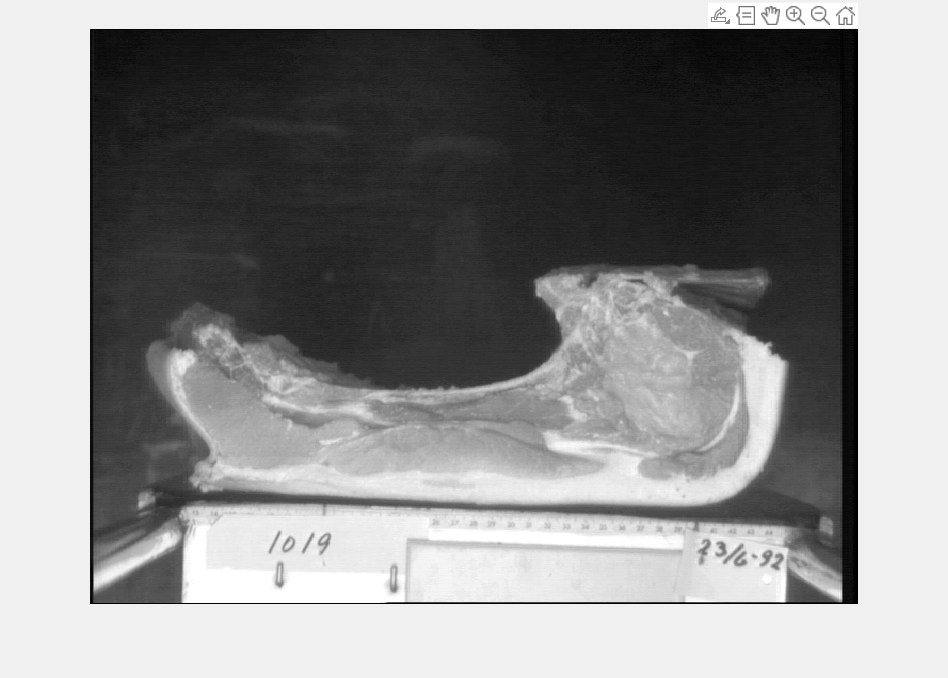

    rect = getrect();

    %J = imcrop(I,rect);
    images{i} = imcrop(I,rect);
end

### Binaritzatizació i percentatge de greix:

#### Etapa 2: Binaritzat de les imatges amb llindar manual

En aquesta estapa utilitzem els llindars escollits a partir dels histogrames per binaritzar la imatge i la llonza.

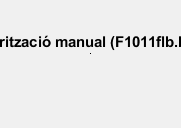

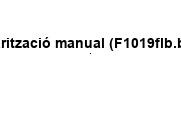

for i = 1:nf  
    J = image(i);
    chuleton = J;
    chuleton(J < llindar_manual_fons(i)) = 0; % imatge sense el fons
    
    llonza = chuleton > 0; % pixels de la llonza a 1
    greix = chuleton > llindar_manual_chuleton(i); % binaritzat de la llonza
    
    imshow(greix), title('Binarització manual (' + convertCharsToStrings(a(i).name) + ')')
    figure

    size_llonza = sum(sum(llonza));
    size_greix = sum(sum(greix));
    perc_greix_manual = (size_greix/size_llonza)*100;
    
    percentatges_manuals(i, 1) = perc_greix_manual;
end

#### Etapa 3: Mostrar l'histograma i escollir el llindar 

En aquest apartat mostrem l'histograma de la imatge per escollir el llindar per eliminar el fons, i seguidament mostrem l'histograma de la llonza per tal de trobar el llindar més adient per binaritzar la pròpia llonza. Els histogrames ens donaran un interval de possibles llindars.

for i = 1:nf  
    J = image{i};
    histogram(J), title('Histograma de la imatge ' + convertCharsToStrings(a(i).name));
    figure
    
    chuleton = J;
    chuleton(J < llindar_manual_fons(i)) = 0; % imatge sense el fons
    llonza = chuleton > 0; % pixels de la llonza a 1
    histogram(chuleton(llonza)), title('Histograma del chuleton ' + convertCharsToStrings(a(i).name));
    figure
end

Brace indexing into the result of a function call is not supported. Assign the result of 'image' to a variable first, then brace
index into it.

#### Etapa 4: Llindar de forma automàtica

En aquest apartat hem trobat els llindars de forma autòmatica utilitzant la funció graythresh que implementa l'Otsu thresholding.

for i = 1:nf    
    J = image(i);
    llindar_llonza = graythresh(J)*256;
    chuleton = J;
    chuleton(J < llindar_llonza) = 0; % imatge sense el fons
    
    llonza = chuleton > 0; % pixels de la llonza a 1
    llindar_greix = graythresh(chuleton(llonza))*256;
    greix = chuleton > llindar_greix; % binaritzat de la llonza
    imshow(greix), title('Binarització automàtica (' + convertCharsToStrings(a(i).name) + ')')
    figure
    
    size_llonza = sum(sum(llonza));
    size_greix = sum(sum(greix));
    perc_greix_auto = (size_greix/size_llonza)*100;
    
    percentatges_auto(i, 1) = perc_greix_auto;
    
end

#### Llindar amb Otsu

% h = imhist(J);
% [f c] = size(J);
% p = h/(f*c);
% 
% m = (0:255).*p(1:256)';
% maxv = 0;
% maxt = 0;
% for t = 1:256
%     w0 = sum(p(1:t));
%     w1 = 1 - w0;
%     nyu0 = (sum(m(1:t)))/w0;
%     nyu1 = (sum(m(t:256)))/w1;
%     ab = w0*w1*(nyu0-nyu1)^2;
%     if (ab > maxv) 
%         maxt = t;
%         maxv = ab;
%     end
% end
% llindar_llonza = maxt;
% J2 = J;
% J2(J < llindar_llonza) = 0; % imatge sense el fons
% imshow(J2);
% 
% 
% llonza = J2 > 0; % pixels de la llonza a 1
% h = imhist(J2(llonza));
% 
% p = h/(sum(sum(llonza)));
% figure
% plot(p)
% m = (0:255).*p(1:256)';
% maxv = 0;
% maxt = 0;
% for t = 1:256
%     w0 = sum(p(1:t));
%     w1 = 1 - w0;
%     nyu0 = (sum(m(1:t)))/w0;
%     nyu1 = (sum(m(t:256)))/w1;
%     ab = w0*w1*(nyu0-nyu1)^2;
%     if (ab > maxv) 
%         maxt = t;
%         maxv = ab;
%     end
% end
% llindar_greix = maxt;
% J3 = J2 > llindar_greix; % binaritzat de la llonza
% imshow(J3);
% greix = J3 > 0;  % pixels del greix a 1
% 
% size_llonza = sum(sum(llonza));
% size_greix = sum(sum(greix));
% perc_greix = (size_greix/size_llonza)*100

#### Llindar amb P-tile

[f c] = size(J);
[h, ~] = imhist(J);
p = h/(f*c);
i = 1;
count = 0;
while (i <= 256) & (count < 0.65)
    count = count + p(i);
    i = i + 1;
end
llindar_llonza = i;
    

#### Generador de la taula

T = table(noms', percentatges_manuals, percentatges_auto, 'VariableNames', {'Names', 'Manual', 'Auto'})